%figure out how many axons are there
axon_number = zeros([numel(data), 1]);
for i = 1:numel(data)
    q = sprintf('image_id = %d', data(i).image_id);
    temp = fetch(sln_image.AxonImageAssociation & q);
    axon_number(i) = temp.axon_id;
end

totalids = unique(axon_number);
idnumber = numel(totalids);
allcolors = turbo(idnumber);

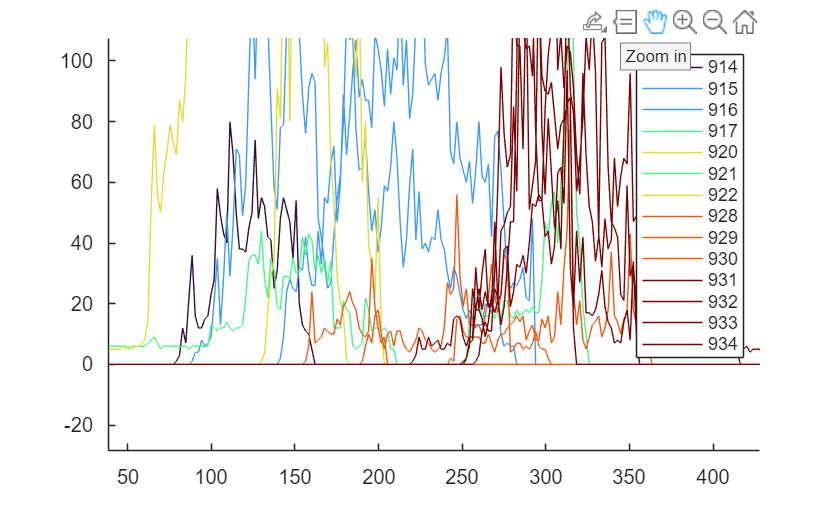

figure;
hold on;
llabels = {};
for i = 1:numel(data)
    q = sprintf('image_id = %d', data(i).image_id);
    temp = fetch(sln_image.AxonImageAssociation & q);
    colorn = find(totalids == temp.axon_id);
    plot(data(i).axon_depth_axis, data(i).axon_density_along_depth, 'Color', allcolors(colorn, :));
    llabels{end+1} = num2str(data(i).image_id);
end
legend(llabels);

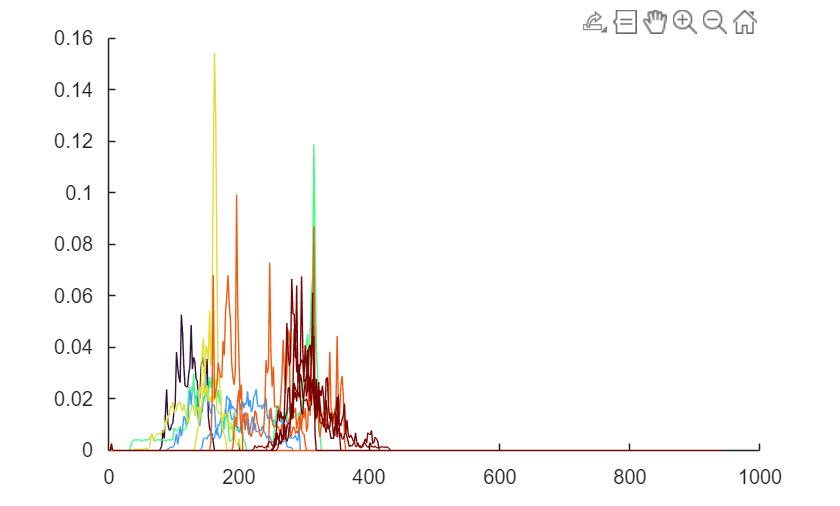

figure;
hold on;
for i = 1:numel(data)
    q = sprintf('image_id = %d', data(i).image_id);
    temp = fetch(sln_image.AxonImageAssociation & q);
    colorn = find(totalids == temp.axon_id);
    plot(data(i).axon_depth_axis, data(i).axon_proportion_along_depth, 'Color', allcolors(colorn, :));
end

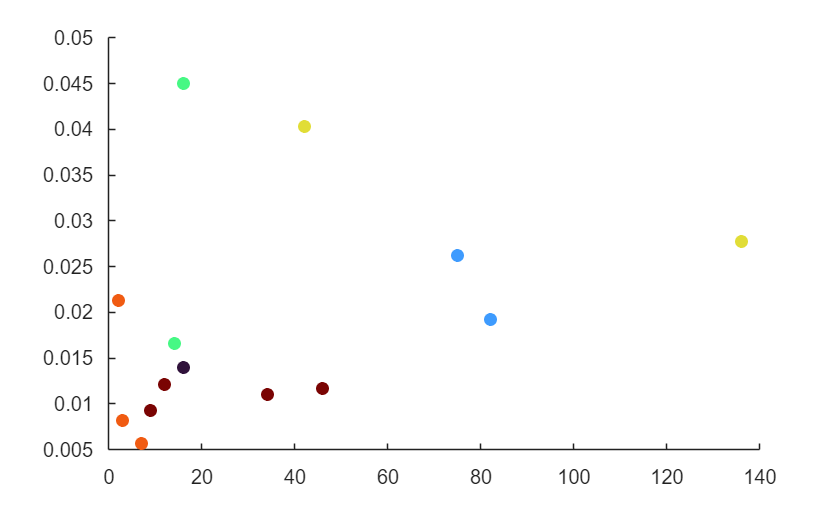

figure;
hold on;
for i = 1:numel(data)
    x = data(i).branch_total;
    y = data(i).axon_density_2dconv;
    q = sprintf('image_id = %d', data(i).image_id);
    temp = fetch(sln_image.AxonImageAssociation & q);
    colorn = find(totalids == temp.axon_id);
    scatter(x, y,'filled', 'MarkerFaceColor',allcolors(colorn, :), 'MarkerEdgeColor', allcolors(colorn, :));
end